% % 读取数据
% T=readtable('D:\temp\apmcm\data\W-Refractive Index.csv')
% %拿到波长
% y=T.Wavelength__m
% x=T{:,2:3}


clc;clear;close all;
% 读取数据
T=readtable('D:\temp\apmcm\data\W-Refractive Index.csv')

T = 200×3 table
    Wavelength__m      n         k   
    _____________    ______    ______

       0.24797       2.6972    2.6847
       0.25289       2.7358    2.6738
       0.25791       2.7728    2.6627
       0.26303       2.8083    2.6514
       0.26825       2.8422      2.64
       0.27358       2.8745    2.6286
       0.27901       2.9052    2.6173
       0.28455       2.9345    2.6063
        0.2902       2.9622    2.5955
       0.29596       2.9884    2.5851
       0.30184       3.0132    2.5752
       0.30783       3.0365    2.5658
       0.31394       3.0585    2.5571
       0.32017       3.0791    2.5492
       0.32653       3.0984    2.5421
       0.33301       3.1165     2.536


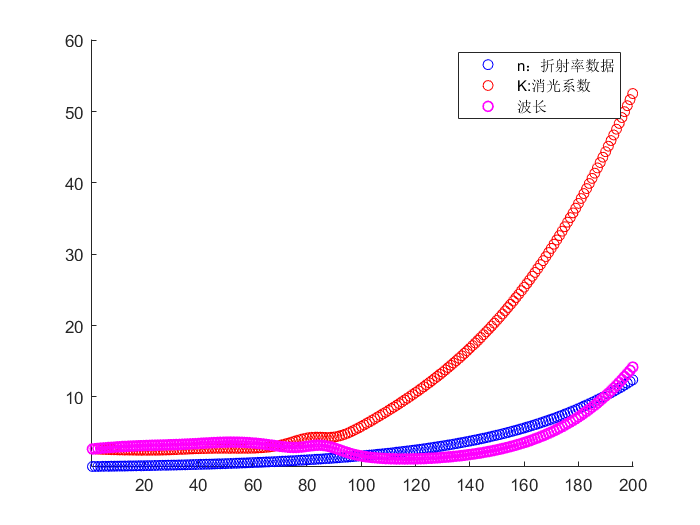

Wavelength__m = T{:,"Wavelength__m"};  % n折射率数据
k = T{:,"k"};    % k:消光系数    
n = T{:,"n"};                    % 波长

figure(1);
hold on;
plot(Wavelength__m,'bo');
plot(k ,'ro');
plot(n,'mo','LineWidth',1);
legend('n：折射率数据','K:消光系数','波长')


% 
% n=x1
% 
% k=x2
% 
% p=fittype('k.^2+b','independent','k')
% f=fit(k,n,p)
% plot(f,k,n);

% f1=fittype('sqrt(k.^2+b)','independent','k','coefficients',{'b'});
% fun= fit(k,n,f1);
% ty1=fun(x1)
% % 其中第一个参数是待拟合的函数表达式，其中得到自变量x需要声明为符号变量，a,b为待拟合的参数。
% % 第二个参数固定为independt(对独立的变量x而言)
% % 第三个参数声明自变量，若是自变量多个则应该写作同第五个表达式中那样
% % 第四个参数固定‘coefficients’表示后面的变量为系数
% % 第五个参数为待拟合的参数，若是多个则用大括号括起。
% % fit函数为具体的拟合函数，三个参数依次为自变量，和因变量以及拟合表达式子。

% 
% clear;clc
% x=k
% y=n
% beta0=[1 9 1];
% beta=nlinfit(x,y,'Rik',beta0)
% x1=0.2:0.01:0.91;
% plot(x,y,'*',x1,Rik(beta,x1))
% 
% ----------------------------------
% function y=Rik(beta,x)
% y=(beta(2)./(log(beta(1)./x))).^(1/beta(3));